# produce a PAH .airfoil file from a selig 1223

clear; close; clc;

## Initialize variables

filename = "PAH_KL_sexy_sexy" % PAH_selig 1223

filename = "PAH_KL_sexy_sexy"

PAH_relaxation_factor = 1.5 % 2 is half stiffness of original 4 is a quater of stiffness of original

PAH_relaxation_factor = 1.5000

## read the file

%airfoilData = fileread("Selig 1223.airfoil");
airfoilData = fileread("KL_sexy_sexy.airfoil");
%airfoilData = fileread("Wortmann FX LIII-142 Re#500k.airfoil");


airfoilData = split(airfoilData,newline)

airfoilData = 14×1 cell array
    {'[Airfoil]←'                                           }
    {'Name=KL sexy sexy 012 132f - ReNum 200k←'             }
    {'Data Source=Summary of Low Speed Airfoil Data Vol. 2←'}
    {'clalpha [1/rad]=7.16←'                                }
    {'alpha_o [deg]=-1.4←'                                  }
    {'c_l_o [-]=0.178←'                                     }
    {'alpha" [deg]=9.55←'                                   }
    {'alpha* [deg]=6.97←'                                   }
    {'c_l* [-]=1.00←'                                       }
    {'alpha_c_l_max [deg]=16←'                              }
    {'c_l_max [-]=1.28←'                                    }
    {'alpha_post_S [deg]=18←'                               }
    {'c_l_post_S [-]=1.26←'                                 }
    {0×0 char                                                }



% extract the value from the file
name = string(extractBetween(airfoilData(2),"=",char(13)));
DataSource = string(extractBetween(airfoilData(3),"=",char(13)));

c_l_alpha = str2double(extractBetween(airfoilData(4),"=",char(13)));
for i = 4:13
    data(i-3) = str2double(extractBetween(airfoilData(i),"=",char(13)));
end
c_l_alpha = data(1);
alpha_0 = deg2rad(data(2));
c_l_0 = data(3);
alpha_prime = deg2rad(data(4));
alpha_star = deg2rad(data(5));
c_l_star = data(6);
alpha_c_l_max = deg2rad(data(7));
c_l_max = data(8);
alpha_post_stall = deg2rad(data(9));
c_l_post_stall = data(10);

% save into airfoil object
airfoil = Airfoil(name, DataSource, c_l_alpha, alpha_0, c_l_0, alpha_star,alpha_prime, c_l_star, alpha_c_l_max, c_l_max, alpha_post_stall, c_l_post_stall)

airfoil =   Airfoil with properties:

                name: "KL sexy sexy 012 132f - ReNum 200k"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 7.1600
             alpha_0: -0.0244
               c_l_0: 0.1780
          alpha_star: 0.1216
         alpha_prime: 0.1667
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.2800
    alpha_post_stall: 0.3142
      c_l_post_stall: 1.2600


## plot airfoil

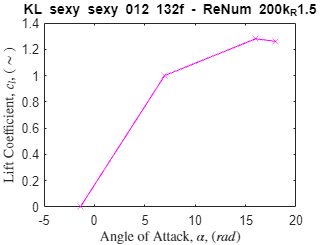

figure;
alphas = rad2deg([airfoil.alpha_0, airfoil.alpha_star, airfoil.alpha_c_l_max, airfoil.alpha_post_stall]);
c_ls = [0, airfoil.c_l_star, airfoil.c_l_max, airfoil.c_l_post_stall];
plot(alphas, c_ls,"m-x" , "DisplayName","R=1 (Rigid)");
hold on
title(airfoil.name + "_R" + PAH_relaxation_factor);
xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");

## now produce a PAH verison

PAH_relaxation_factors = [1.5, 2, 3, 4];
for i = 1:length(PAH_relaxation_factors)
    PAH_relaxation_factor = PAH_relaxation_factors(i)
    % we know that the C_L_mad is unchanged 
    % lets just try streching it by a ratio of 2:1 around c_l_max
    
    alpha_c_l_max_PAH = airfoil.alpha_c_l_max; % stall remins unchanged
    
    % lift curve slope
    alpha_0_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_0)*PAH_relaxation_factor; % half the lift curve slope
    c_l_alpha_PAH = airfoil.c_l_alpha/PAH_relaxation_factor
    % nonlinear region
    alpha_star_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_star)*PAH_relaxation_factor; % half the lift curve slope
    % post stall
    alpha_post_stall_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_post_stall)*PAH_relaxation_factor; % half the lift curve slope
    % alpha prime
    alpha_prime_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_prime)*PAH_relaxation_factor; % half the lift curve slope
    
    airfoil_PAH = Airfoil("PAH_"+name+"_R"+PAH_relaxation_factor, DataSource, c_l_alpha_PAH, alpha_0_PAH, c_l_0, alpha_star_PAH, alpha_prime, c_l_star, alpha_c_l_max, c_l_max, alpha_post_stall_PAH, c_l_post_stall)
    
    alphas = rad2deg([airfoil_PAH.alpha_0, airfoil_PAH.alpha_star, airfoil_PAH.alpha_c_l_max, airfoil_PAH.alpha_post_stall]);
    c_ls = [0, airfoil_PAH.c_l_star, airfoil_PAH.c_l_max, airfoil_PAH.c_l_post_stall];
    
    plot(alphas, c_ls,"--x", "DisplayName",sprintf("R=%g",PAH_relaxation_factor));
    title(airfoil.name);
    xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
    ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");
end

PAH_relaxation_factor = 1.5000

c_l_alpha_PAH = 4.7733

airfoil_PAH =   Airfoil with properties:

                name: "PAH_KL sexy sexy 012 132f - ReNum 200k_R1.5"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 4.7733
             alpha_0: -0.1763
               c_l_0: 0.1780
          alpha_star: 0.0428
         alpha_prime: 0.1667
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.2800
    alpha_post_stall: 0.3316
      c_l_post_stall: 1.2600


PAH_relaxation_factor = 2

c_l_alpha_PAH = 3.5800

airfoil_PAH =   Airfoil with properties:

                name: "PAH_KL sexy sexy 012 132f - ReNum 200k_R2"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 3.5800
             alpha_0: -0.3281
               c_l_0: 0.1780
          alpha_star: -0.0360
         alpha_prime: 0.1667
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.2800
    alpha_post_stall: 0.3491
      c_l_post_stall: 1.2600


PAH_relaxation_factor = 3

c_l_alpha_PAH = 2.3867

airfoil_PAH =   Airfoil with properties:

                name: "PAH_KL sexy sexy 012 132f - ReNum 200k_R3"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 2.3867
             alpha_0: -0.6318
               c_l_0: 0.1780
          alpha_star: -0.1936
         alpha_prime: 0.1667
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.2800
    alpha_post_stall: 0.3840
      c_l_post_stall: 1.2600


PAH_relaxation_factor = 4

c_l_alpha_PAH = 1.7900

airfoil_PAH =   Airfoil with properties:

                name: "PAH_KL sexy sexy 012 132f - ReNum 200k_R4"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 1.7900
             alpha_0: -0.9355
               c_l_0: 0.1780
          alpha_star: -0.3512
         alpha_prime: 0.1667
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.2800
    alpha_post_stall: 0.4189
      c_l_post_stall: 1.2600


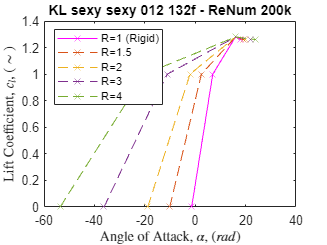

legend("Location","northwest")